# Fourier Analysis of Signals Using DFT (250 Points)

**Dear Student, **

**At the end of this exercise, you will be able to **

- **find out an estimate of frequency content of a discrete-time sequence,  **

- **comment on resolution and leakage of a window and its impact on the frequency analysis, and **

- **compare different types of windows.**

- **use short-term Fourier transform and obtain power spectral density of a signal. **

Let $x[n] =  A_0\cos(w_0n) +  A_1\cos(w_1n), n \in \mathbb{Z}$ be the discrete-time signal obtained by sampling $x(t)$with sampling frequency $T_s$. 

Write down possible expressions for $x(t)$ here:  $\textrm{ENTER}\;\textrm{YOUR}\;\textrm{ANSWER}\;\textrm{HERE}\ldotp$ $x(t) =  A_0\cos(w_0 t / T_s) +  A_1\cos(w_1 t / T_s), \forall \; t$

Usually, we cannot obtain the sequence $x[n]$for all the time duration, i.e., for $-\infty $to $+\infty
$. Further, even if you are able to collect a large number of samples, we will not be able to compute its DFT for frequency analysis.  Let us assume that we have $x[n]$values available for $0\leq n\leq L-1$only using which we are required to do frequency analysis. One way to go forward is, we assume that $x[n]=0$ for $n\notin \{0,L-1\}$.  That is, we have the windowed sequence, $v[n]$, defined as follows:$v[n] = x[n]w[n]$, where $w[n] = 1$for $0\leq n\leq L-1$ and $w[n] =0$, otherwise. This window is called as the rectangular window. 

#### Coding Question (10 points)

Write a code to get $x[n], w[n] $and $v[n]$

w0 = [2*pi/6,2*pi/14,2*pi/14,2*pi/14];
w1 = [2*pi/3,2*pi/15,2*pi/12,4*pi/25];
A1 = 1;
A2 = 1;
L =  64;   % Window length

n= 0:L-1;
% EXERCISE: Construct x[n] defined above
x = A1*cos(w0(:)*n)+A2*cos(w1(:)*n)

x =     2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000
    2.0000    1.8145    1.2926    0.5315   -0.3270   -1.1235   -1.7100   -1.9781   -1.8791   -1.4325   -0.7225    0.1180    0.9325    1.5701    1.9135    1.9010    1.5370    0.8917    0.0865   -0.7280   -1.4010   -1.8090   -1.8791   -1.6016   -1.0315   -0.2775    0.5190    1.2100    1.6691    1.8145    1.6235    1.1361    0.4466   -0.3145   -1.0055   -1.5000   -1.7100   -1.6016   -1.2007   -0.5865    0.1235    0.7964    1.3090    1.5701    1.5370    1.2225    0.6910    0.0456   -0.5920   -1

% EXERCISE Define a rectangular window of length L, w[n]
rectWindow = ones(1,L)

rectWindow =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


% EXERCISE: Compute the windowed sequence, v[n]
v= x.*rectWindow

v =     2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000
    2.0000    1.8145    1.2926    0.5315   -0.3270   -1.1235   -1.7100   -1.9781   -1.8791   -1.4325   -0.7225    0.1180    0.9325    1.5701    1.9135    1.9010    1.5370    0.8917    0.0865   -0.7280   -1.4010   -1.8090   -1.8791   -1.6016   -1.0315   -0.2775    0.5190    1.2100    1.6691    1.8145    1.6235    1.1361    0.4466   -0.3145   -1.0055   -1.5000   -1.7100   -1.6016   -1.2007   -0.5865    0.1235    0.7964    1.3090    1.5701    1.5370    1.2225    0.6910    0.0456   -0.5920   -1

Now, we will compute its DFT using the Matlab in-built function ([fft](https://in.mathworks.com/help/matlab/ref/fft.html)). 

#### Coding Question (10 points)

Compute $N$-point DFT, $V[k]$ of $v[n]$ and plot $V[k]$ from $k\in [0, N-1]$

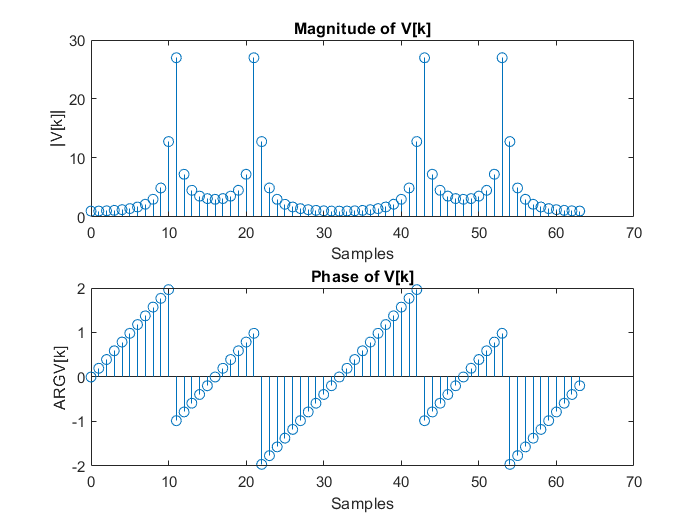

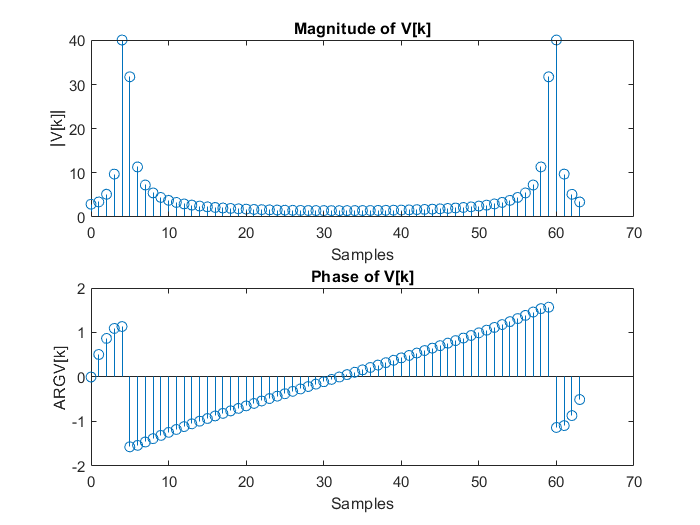

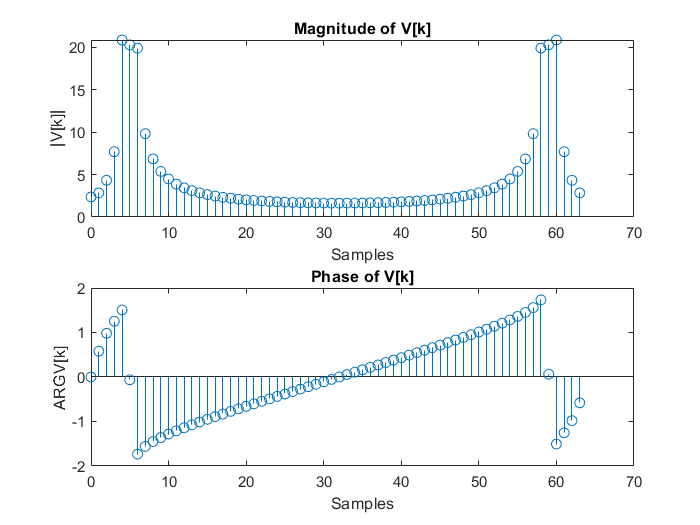

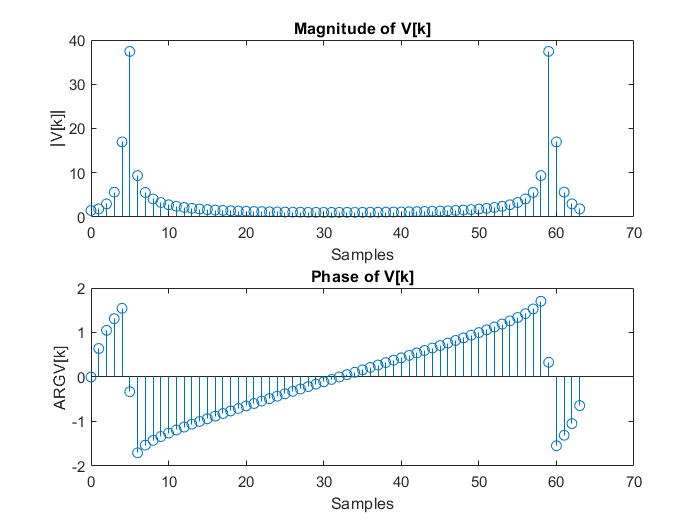

N = [L]; % EXERCISE: Define a suitable N
 
for i=1:4
    V = fft(v(i,:),N); % EXERCISE: Compute N-point DFT
    
    figure();
    
    subplot(2,1,1);
    stem(0:N-1,abs(V)); %  EXERCISE: Plot Magnitude of V
    xlabel('Samples')
    ylabel('|V[k]|')
    title('Magnitude of V[k]')
    
    subplot(2,1,2); 
    stem(0:N-1,angle(V)); %  EXERCISE: Plot Phase of V
    xlabel('Samples')
    ylabel('ARG{V[k]}')
    title('Phase of V[k]')
end

It is bit difficult to read the above plots as we do not readily see which samples correspond to which discrete-time frequency. Hence, let us try to view the DTFT of v[n] (approximate). Let us first compute the DTFT of $w[n]$.

#### Coding Question (10 points)

Compute the DTFT of w[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

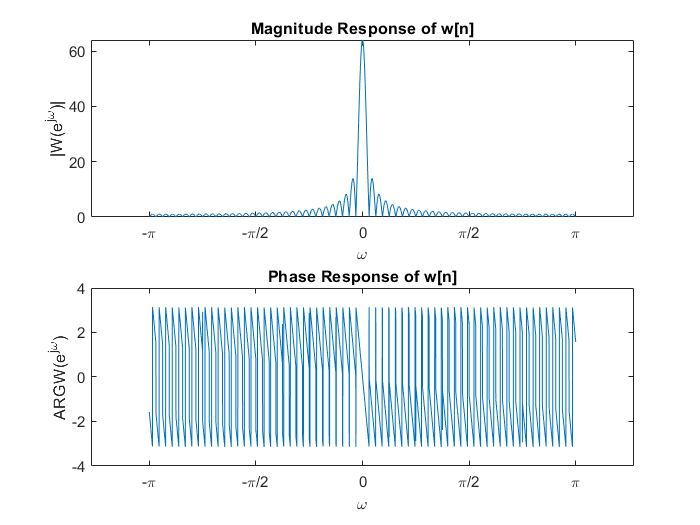

N = [10000]; % EXERCISE: Define a suitable N

omega = -pi:2*pi/N:pi; % EXERCISE: Compute sample points of discrete-time frequency
W = zeros(1,length(omega));
% EXERCISE: Compute N-point DFT
for w = 1:length(omega)
    for n = 1:length(rectWindow)
        W(w) = W(w) + rectWindow(n)*exp(-1j*omega(w)*n);
    end
end

subplot(2,1,1);
plot(omega, abs(W)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|W(e^{j\omega})|')
title('Magnitude Response of w[n]')
xticks(-pi:pi/2:pi);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

subplot(2,1,2); 
plot(omega, angle(W)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('ARG{W(e^{j\omega})}')
title('Phase Response of w[n]')
xticks(-pi:pi/2:pi);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

#### Coding Question 10 points)

Compute the DTFT of v[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

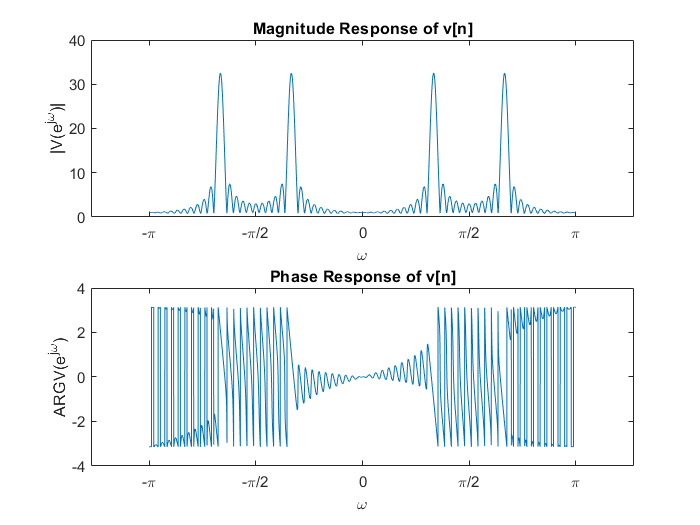

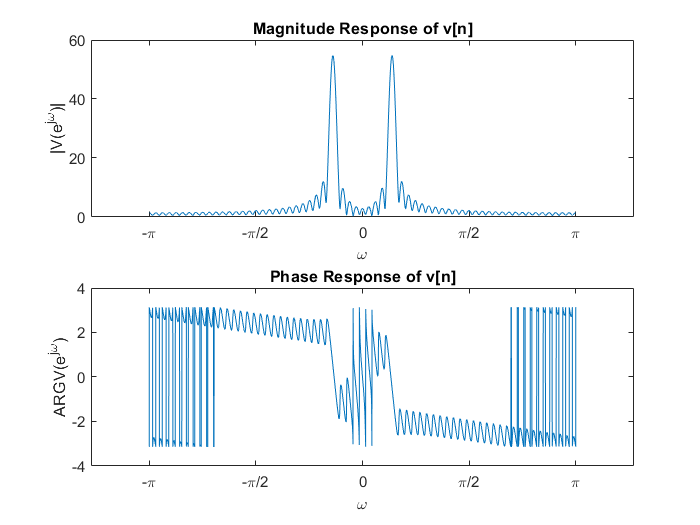

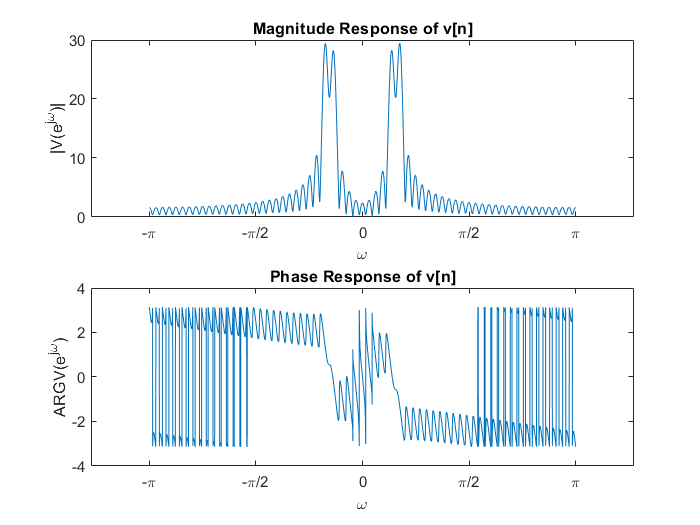

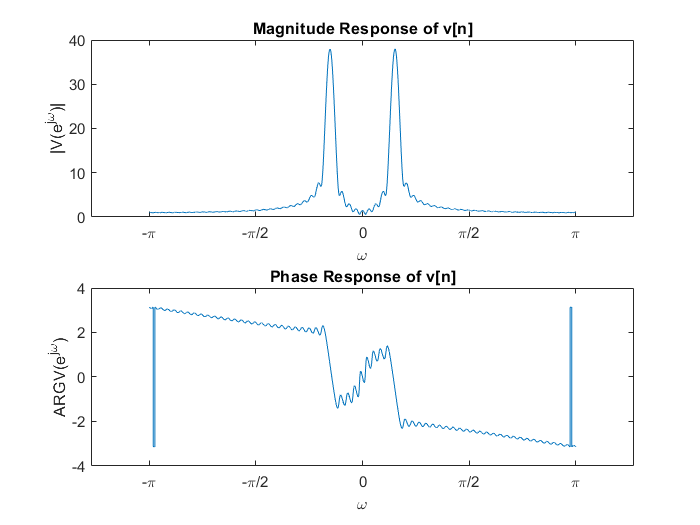

N = [10000]; % EXERCISE: Define a suitable N
omega = -pi:2*pi/N:pi;% EXERCISE: Compute sample points of discrete-time frequency
V = zeros(size(v,1),length(omega)); 
% EXERCISE: Compute N-point DFT
for i =1:size(v,1)
    for w = 1:length(omega)
        for n = 1:size(v,2)
            V(i,w) = V(i,w) + v(i,n)*exp(-1j*omega(w)*n);
        end
    end
end
%  EXERCISE: Plot Magnitude  of V
for i =1:size(v,1)
    figure();
    
    subplot(2,1,1);
    plot(omega, abs(V(i,:)));
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title('Magnitude Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

    subplot(2,1,2); 
    plot(omega, angle(V(i,:))); %  EXERCISE: Plot Magnitude  of V
    xlabel('\omega')
    ylabel('ARG{V(e^{j\omega})}')
    title('Phase Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
end

#### Coding Question  (10 points)

Now, suppose the $x(t)$ was sampled at sampling period of $T_s$, then plot $X(j\Omega)$, your estimate of the continuous-time Fourier transform of $x(t)$. 

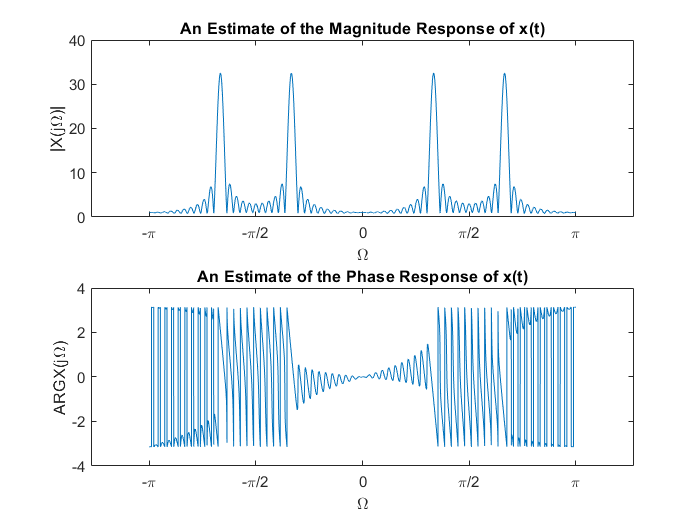

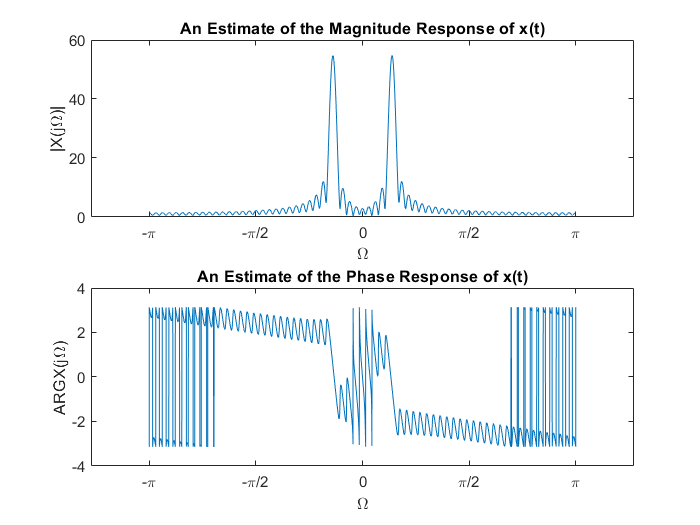

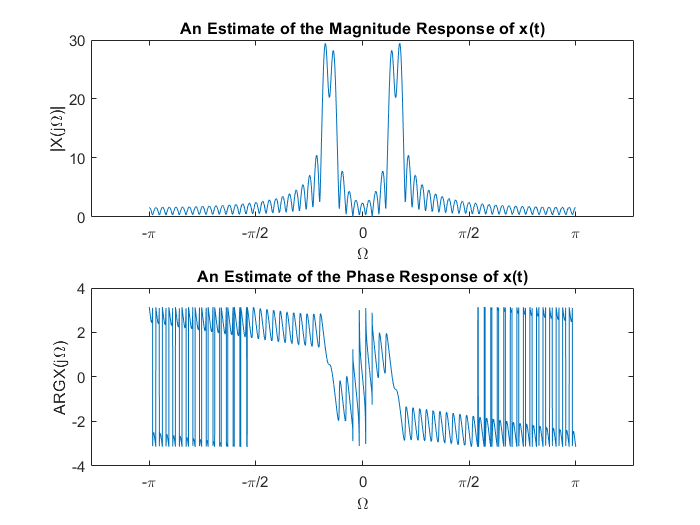

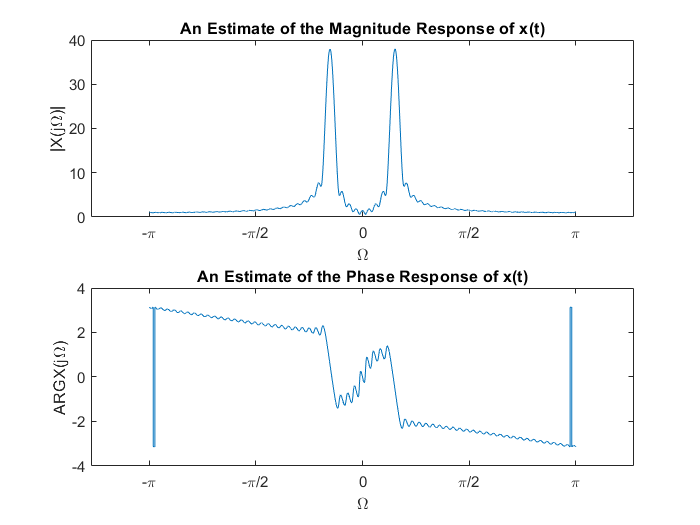

Ts = [1] ; % EXERCISE: Choose a sensible sampling frequency

Omega = omega/Ts; % EXERCISE: Construct continuous-time frequency from discrete-time frquency
%EXERCISE:  Compute the continuous-time Fourier transform
X_jOmega = zeros(size(x,1),length(Omega));
for i =1:size(x,1)
    for w = 1:length(Omega)
        for n = 1:size(x,2)
            X_jOmega(i,w) = X_jOmega(i,w) + x(i,n)*exp(-1j*Omega(w)*n);
        end
    end
end
for i =1:size(x,1)
    figure();
    
    subplot(2,1,1);
    plot(Omega,abs(X_jOmega(i,:))); %  EXERCISE: Plot Magnitude  of V
    xlabel('\Omega')
    ylabel('|X(j\Omega)|')
    title('An Estimate of the Magnitude Response of x(t)')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

    subplot(2,1,2); 
    plot(Omega,angle(X_jOmega(i,:))); %  EXERCISE: Plot Magnitude  of V
    xlabel('\Omega')
    ylabel('ARG{X(j\Omega)}')
    title('An Estimate of the Phase Response of x(t)')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
end

#### Inference Question (40 points)

Now, repeat the above four questions for 

- 
$$w_0 = 2\pi/14, w_1 = 2\pi/15$$


- 
$$w_0 = 2\pi/14, w_1 = 2\pi/12$$


- 
$$w_0 = 2\pi/14, w_1 = 4\pi/25$$


- What do you observe on the number of peaks?  

- How does your observation change if you change $L$? 

- How does your observation change if you change $N$? 

- Do the amplitudes of $|V[k]|$reflect that of $|V(e^{j\omega})|$? Why? 

- Do the amplitudes of $|V(e^{j\omega})|$ reflect that of $|X(e^{j\omega})|$?  Why? 

    * WRITE YOUR ANSWER HERE.*

*As wo and w1 seperation increases, the peaks can be resolved better. For clsoe w0 and w1, 1 peak is observed and for w0 and w1 distinct, 2 peaks are observed*

*If L< length of signal, information will be lost as some part of signal will be nulled*

*For N< length of signal, the DFT is doesnt accurately resolve the 2 peaks. For large values, the DFT is close to DTFT*

*For N> length of signal, DFT amplitude reflects DTFT amplitude. As N increases, the seperation between succesive w's decreases and w behaves more and more like a continuous variable and so DFT approaches DTFT*

*For L > length of signal, DTFT amplitude of v reflects DTFT amplitude of x. If L < length of signal, some information is lost while windowing and DTFT amplitude of v differs greatly DTFT amplitude of x*

In the above, we observed $x[n]$ through a rectangular window. Let's now observe $x[n]$ through other types of windows and explore what we will see. 

Now, use this link for help ([https://in.mathworks.com/help/dsp/ref/windowfunction.html](https://in.mathworks.com/help/dsp/ref/windowfunction.html)) and compute the DTFT of $v[n]$ over $[-\pi, \pi]$when

- $w[n]$is a Hamming window

- $w[n]$is a Hanning window

- $w[n]$is a Bartlet window

- $w[n]$is a Kaiser window

Note that you have already used the Boxcar window earlier above. 

#### Coding Question  (40 points)

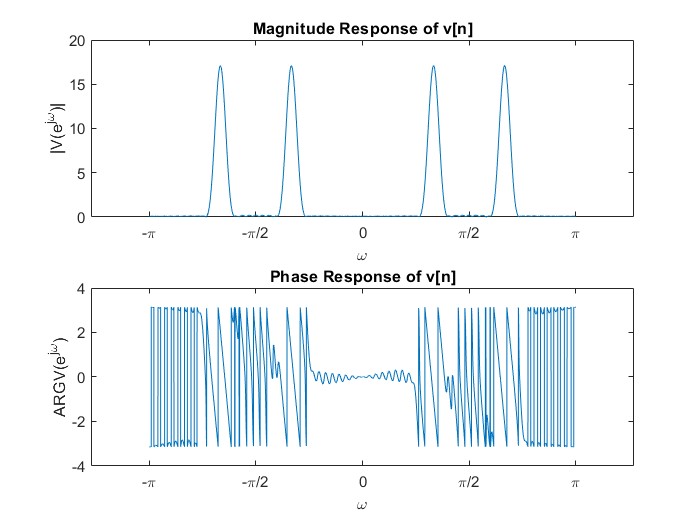

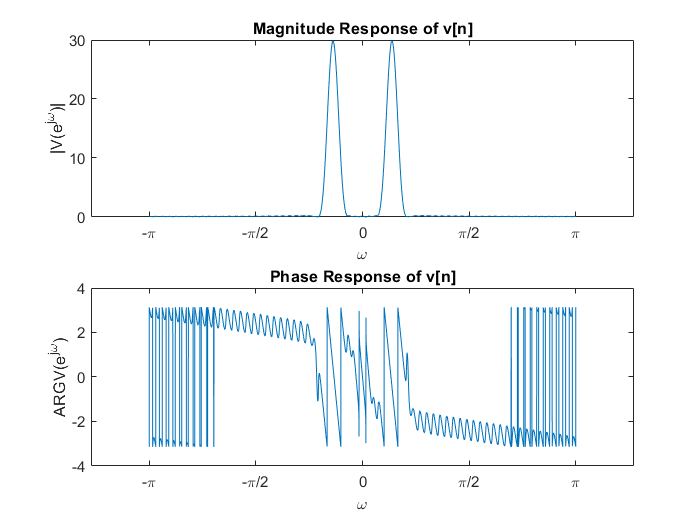

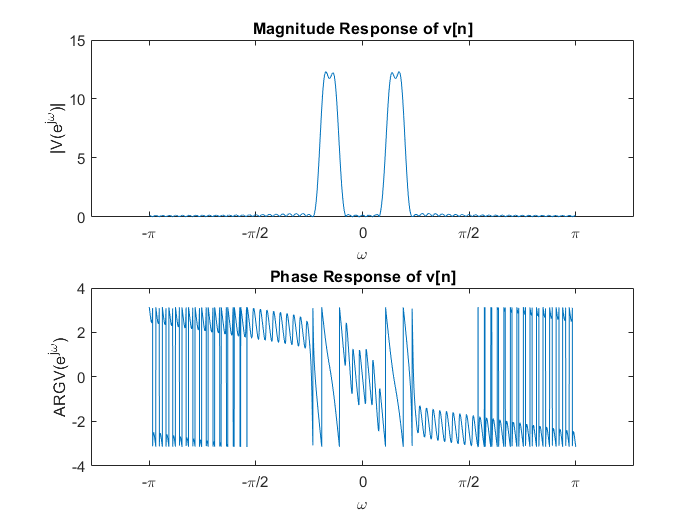

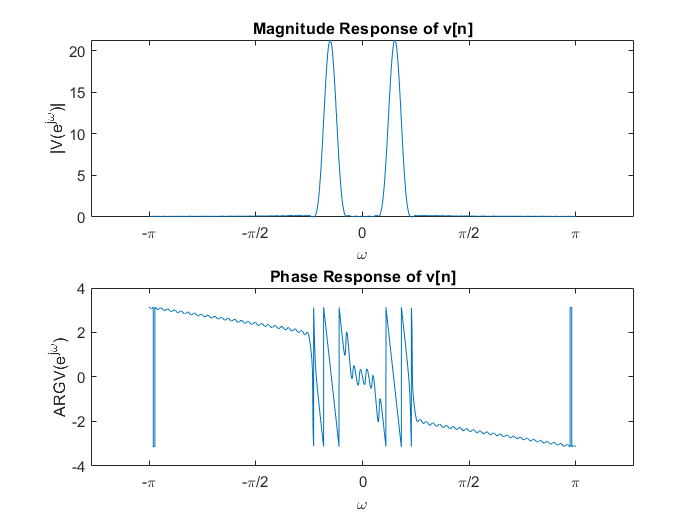

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A HAMMING WINDOW
w0 = [2*pi/6,2*pi/14,2*pi/14,2*pi/14];
w1 = [2*pi/3,2*pi/15,2*pi/12,4*pi/25];
A1 = 1;
A2 = 1;
n= 0:L-1;
x = A1*cos(w0(:)*n)+A2*cos(w1(:)*n);
L = [64];
w = hamming(L)';
v= x.*w;
N = [10000]; % EXERCISE: Define a suitable N
omega = -pi:2*pi/N:pi;% EXERCISE: Compute sample points of discrete-time frequency
V = zeros(size(v,1),length(omega)); 
% EXERCISE: Compute N-point DFT
for i =1:size(v,1)
    for w = 1:length(omega)
        for n = 1:size(v,2)
            V(i,w) = V(i,w) + v(i,n)*exp(-1j*omega(w)*n);
        end
    end
end
%  EXERCISE: Plot Magnitude  of V
for i =1:size(v,1)
    figure();
    
    subplot(2,1,1);
    plot(omega, abs(V(i,:)));
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title('Magnitude Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

    subplot(2,1,2); 
    plot(omega, angle(V(i,:))); %  EXERCISE: Plot Magnitude  of V
    xlabel('\omega')
    ylabel('ARG{V(e^{j\omega})}')
    title('Phase Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
end

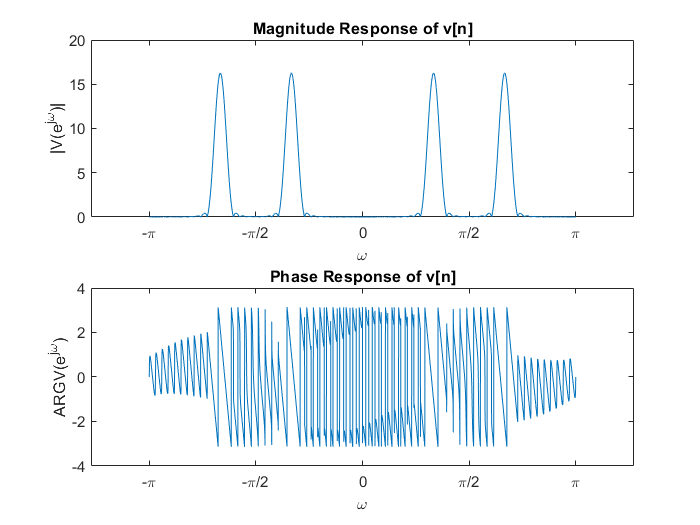

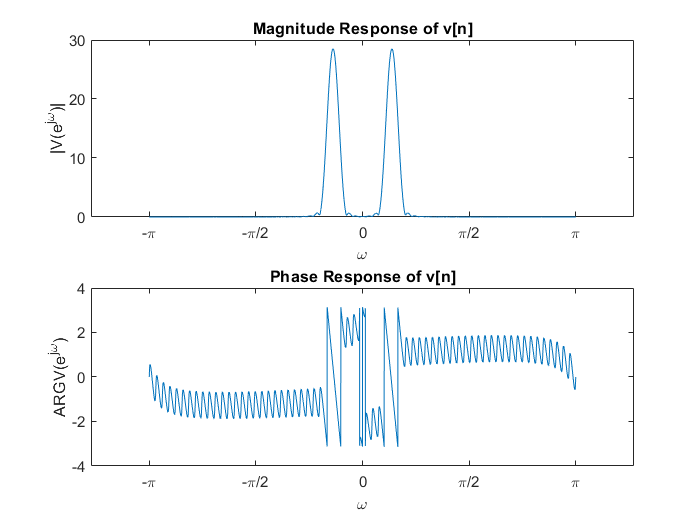

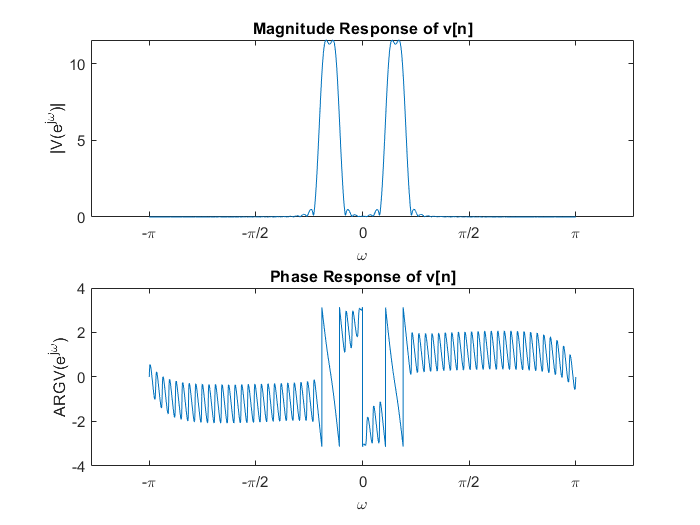

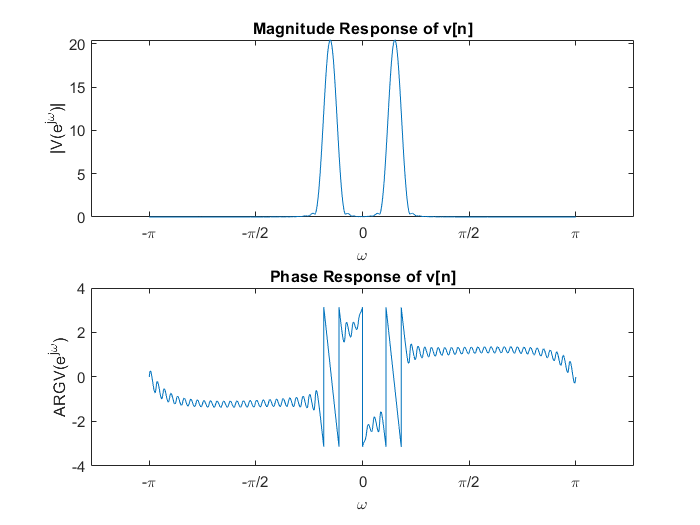

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Hanning WINDOW
w0 = [2*pi/6,2*pi/14,2*pi/14,2*pi/14];
w1 = [2*pi/3,2*pi/15,2*pi/12,4*pi/25];
A1 = 1;
A2 = 1;
n= 0:L-1;
x = A1*cos(w0(:)*n)+A2*cos(w1(:)*n);
L = [64];
w = hanning(L)';
v= x.*w;
N = [10000]; % EXERCISE: Define a suitable N
omega = -pi:2*pi/N:pi;% EXERCISE: Compute sample points of discrete-time frequency
V = zeros(size(v,1),length(omega)); 
% EXERCISE: Compute N-point DFT
for i =1:size(v,1)
    for w = 1:length(omega)
        for n = 1:size(v,2)
            V(i,w) = V(i,w) + v(i,n)*exp(-1j*omega(w)*n);
        end
    end
end
%  EXERCISE: Plot Magnitude  of V
for i =1:size(v,1)
    figure();
    
    subplot(2,1,1);
    plot(omega, abs(V(i,:)));
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title('Magnitude Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

    subplot(2,1,2); 
    plot(omega, angle(V(i,:))); %  EXERCISE: Plot Magnitude  of V
    xlabel('\omega')
    ylabel('ARG{V(e^{j\omega})}')
    title('Phase Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
end

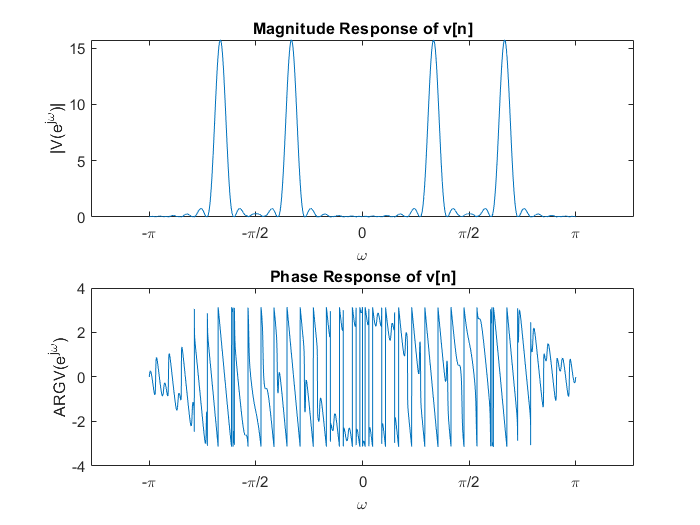

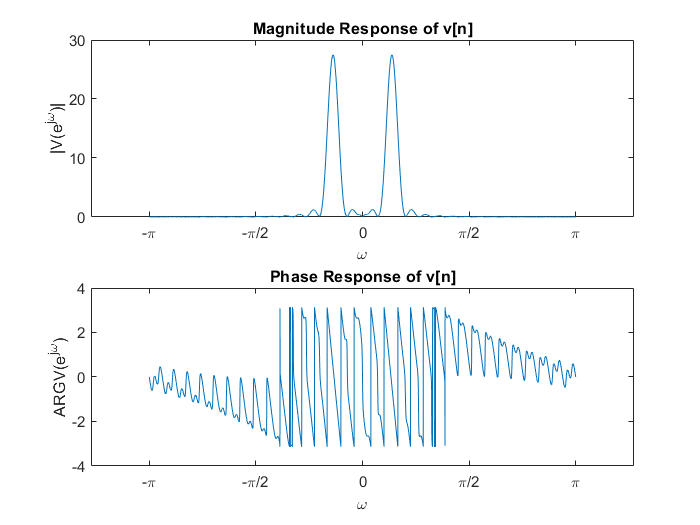

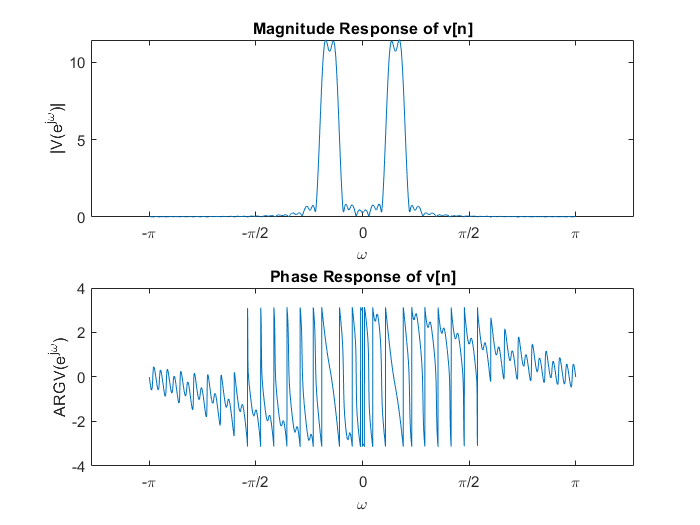

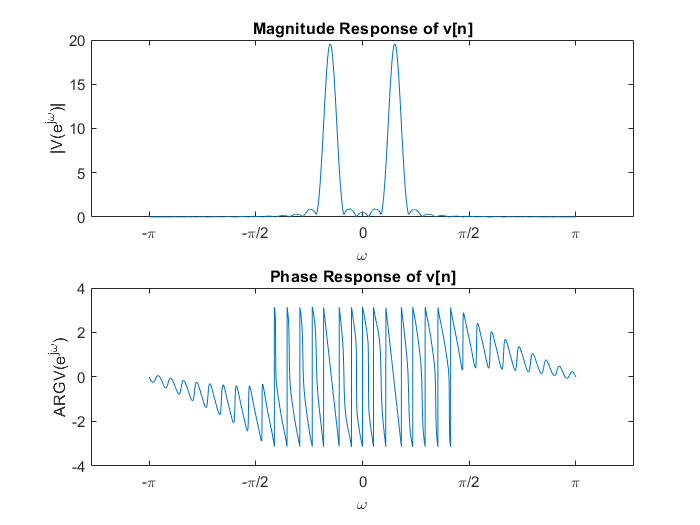

%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Bartlet WINDOW
w0 = [2*pi/6,2*pi/14,2*pi/14,2*pi/14];
w1 = [2*pi/3,2*pi/15,2*pi/12,4*pi/25];
A1 = 1;
A2 = 1;
n= 0:L-1;
x = A1*cos(w0(:)*n)+A2*cos(w1(:)*n);
L = [64];
w = bartlett(L)';
v= x.*w;
N = [10000]; % EXERCISE: Define a suitable N
omega = -pi:2*pi/N:pi;% EXERCISE: Compute sample points of discrete-time frequency
V = zeros(size(v,1),length(omega)); 
% EXERCISE: Compute N-point DFT
for i =1:size(v,1)
    for w = 1:length(omega)
        for n = 1:size(v,2)
            V(i,w) = V(i,w) + v(i,n)*exp(-1j*omega(w)*n);
        end
    end
end
%  EXERCISE: Plot Magnitude  of V
for i =1:size(v,1)
    figure();
    
    subplot(2,1,1);
    plot(omega, abs(V(i,:)));
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title('Magnitude Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

    subplot(2,1,2); 
    plot(omega, angle(V(i,:))); %  EXERCISE: Plot Magnitude  of V
    xlabel('\omega')
    ylabel('ARG{V(e^{j\omega})}')
    title('Phase Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
end

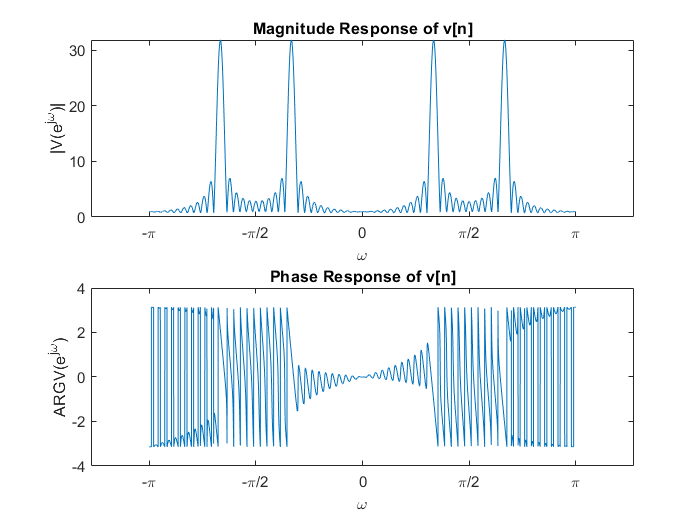

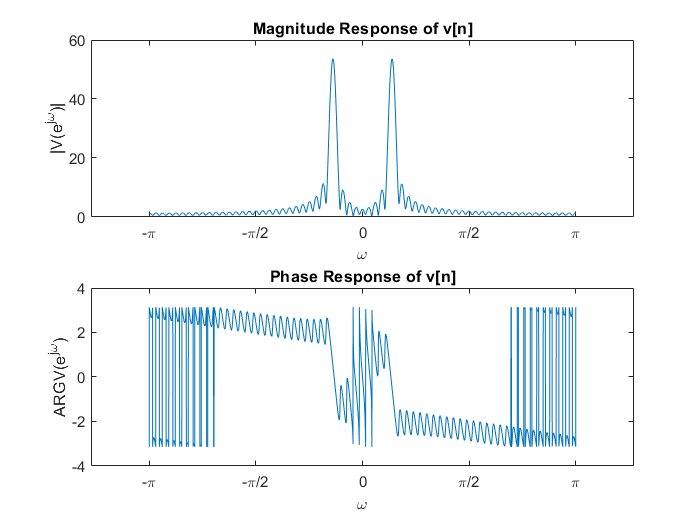

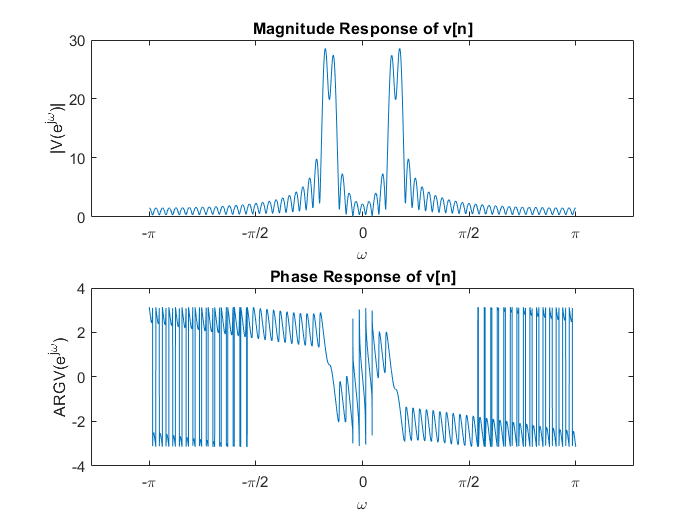

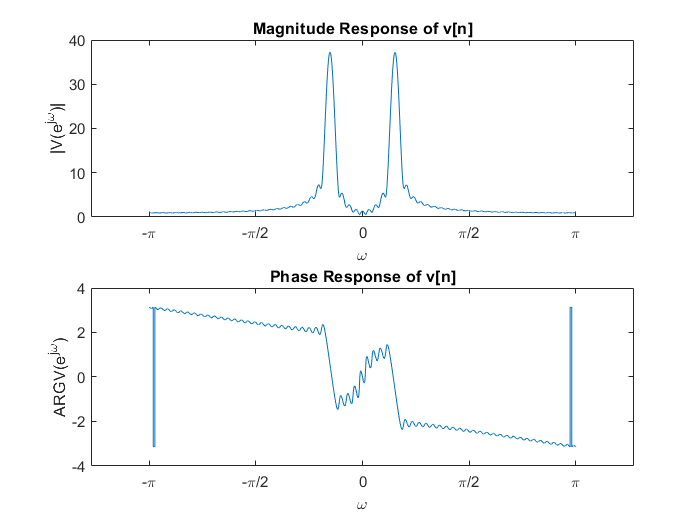

%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Kaiser WINDOW
w0 = [2*pi/6,2*pi/14,2*pi/14,2*pi/14];
w1 = [2*pi/3,2*pi/15,2*pi/12,4*pi/25];
A1 = 1;
A2 = 1;
n= 0:L-1;
x = A1*cos(w0(:)*n)+A2*cos(w1(:)*n);
L = [64];
w = kaiser(L)';
v= x.*w;
N = [10000]; % EXERCISE: Define a suitable N
omega = -pi:2*pi/N:pi;% EXERCISE: Compute sample points of discrete-time frequency
V = zeros(size(v,1),length(omega)); 
% EXERCISE: Compute N-point DFT
for i =1:size(v,1)
    for w = 1:length(omega)
        for n = 1:size(v,2)
            V(i,w) = V(i,w) + v(i,n)*exp(-1j*omega(w)*n);
        end
    end
end
%  EXERCISE: Plot Magnitude  of V
for i =1:size(v,1)
    figure();
    
    subplot(2,1,1);
    plot(omega, abs(V(i,:)));
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title('Magnitude Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

    subplot(2,1,2); 
    plot(omega, angle(V(i,:))); %  EXERCISE: Plot Magnitude  of V
    xlabel('\omega')
    ylabel('ARG{V(e^{j\omega})}')
    title('Phase Response of v[n]')
    xticks(-pi:pi/2:pi);
    xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
end

#### Inference Question  (20 points)

- What do you observe on the number of peaks and their amplitudes?

- Give a short comparison of different windows on  the above terms (on the number of peaks and their amplitudes) that you can observe. 

    * WRITE YOUR ANSWER HERE.*

*For w0 and w1 distinct, the number of peaks observed was 2 in all cases but as w0 and w1 keep getting closer to each other, the number of peaks become 1 as resolution is not good enough.*

*For number of peaks, the resolution sequence is : *Hamming window = Hanning window = Bartlet window < Kaiser window; where Kaiser window gives best resolution of peaks.

For main lobe amplitude, the sequence is :  Hanning window = Bartlet window < Hamming window < Kaiser window

For side lobe amplitude, the sequence is : Hamming window < Hanning window < Bartlet window < Kaiser window

## Short-Time Fourier Transform (50 Points)

In the above material, we assume that the frequencies and amplitudes of the sinusoids do not change with time. However, in practice, usually amplitudes and frequencies of a signal change with time. For analyzing the frequency content of that we consider only a small window and analyse its frequency content, and slide the window to look at the frequency content of the next window and so on. This is called the Short-Time Fourier Transform. 

Now read the first page of Section 10.3 of "Discrete-Time Signal Processing", 2nd Edition by Alan V. Oppenheim, Ronald Schafer and John R. Buck. 

- How is the short-time Fourier transform defined as, for a sequence $x[n]$.

        ANSWER:  $ ENTER~YOUR~ANSWER~HERE$==== $X\left\lbrack n,\lambda \right\rbrack =\sum_{-\infty \;}^{\infty \;} x\left\lbrack n+m\right\rbrack w\left\lbrack m\right\rbrack e^{-j\lambda m} \;$

- Now, construct the following frequency modulated chirp signal: $x[n] = \cos(\omega_0 n^2), $ where $\omega_0 = 2\pi\times 7.5\times10^{-6}. $

n = 1:10000;
w0 = 2*pi*7.5*10^-6

w0 = 4.7124e-05

N=1000;
x = [cos(w0*n.^2)] % ENTER YOUR CODE HERE

x =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9997    0.9996    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9985    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9965    0.9962    0.9958    0.9955    0.9950    0.9946    0.9941    0.9936    0.9931


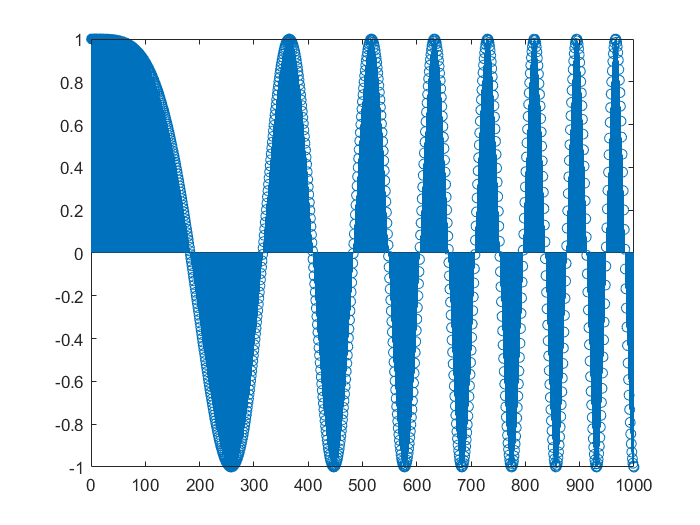

figure();
stem(x(1:N))

- Now compute the short-term Fourier transform of $x[n], $ with rectangular window, $w[n]$  of some L  length. 

L  = [250]; % LENGTH OF THE RECTANGULAR WINDOW
w = [ones(1,L),zeros(1,length(n)-L)]; % RECTANGULAR WINDOW
lambda = [0:2*pi/100:2*pi];
X = [zeros(1000,length(lambda))]; % COMPUTE STFT of x[n] using rectnagluar window w[n].
for l = 1:length(lambda)
    for n = 1:N
        for m=1:1000
            X(n,l) = X(n,l)+x(n+m)*w(m)*exp(-1j*l*m);
        end
    end
end

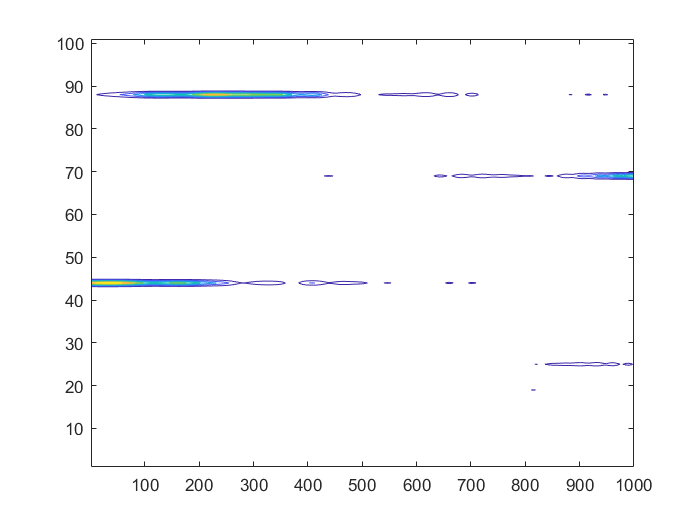

% DISPLAY THE IMAGE IN A TWO DIMENSIONAL PLOT.    
contour(abs(X'))

- Now use [spectrogram](https://in.mathworks.com/help/signal/ref/spectrogram.html) to compute the short-time Fourier transform of the above $x[n]$ and compare it with what you had got. 

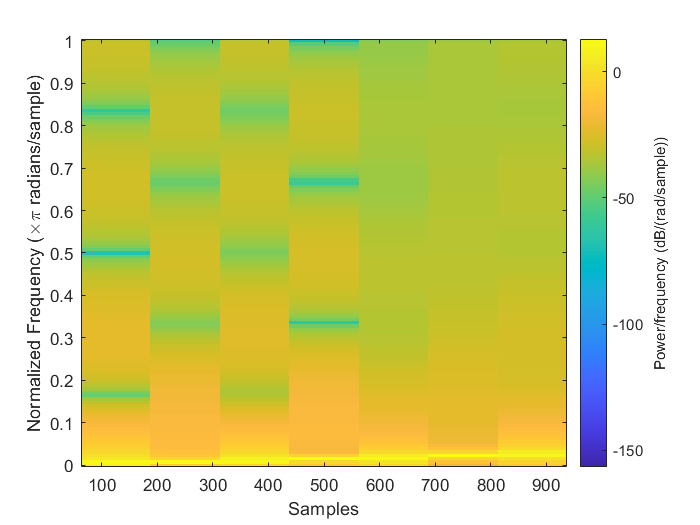

%WRITE YOUR CODE HERE
s = spectrogram(x(1:N),rectwin(L));
spectrogram(x(1:N),rectwin(L),'yaxis')

# Practical Experiment (50 Points)

- Now count 1 to 5 in any language of your interest (try your mother tongue) and record it.

% COUNT 1-5 AND RECORD IT.
rec = audiorecorder;
disp('Start')

Start


recordblocking(rec, 5);
disp('End');

End


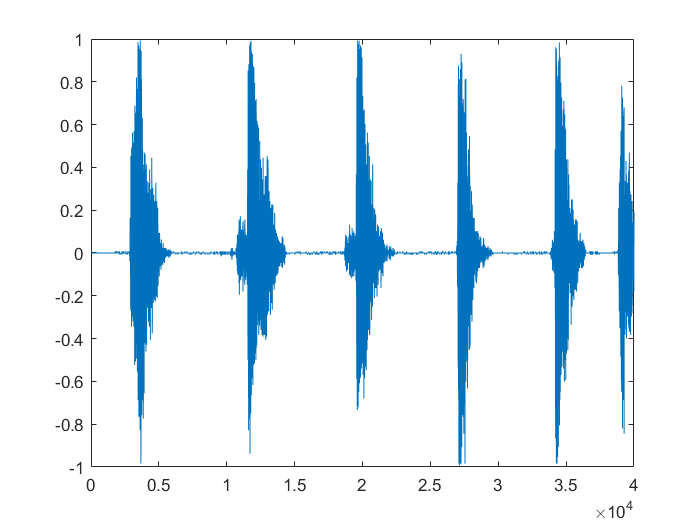

x = getaudiodata(rec);
plot(x) %plot freq graph

- Now compute the spectrogram of the signal you have recorded

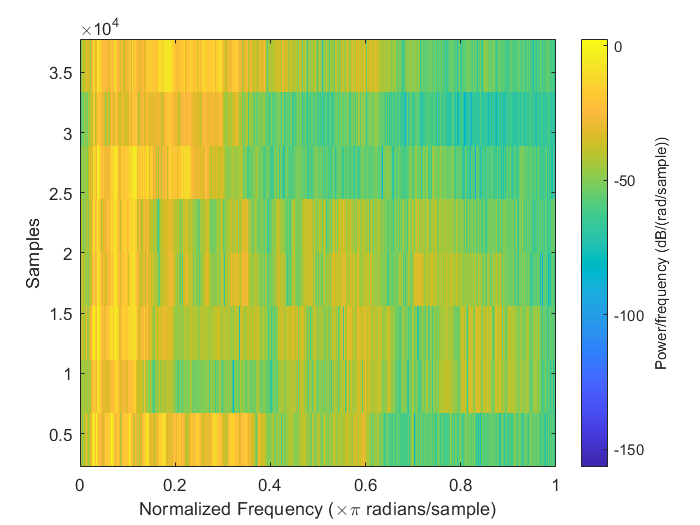

% COMPUTE THE SPECTROGRAM
spectrogram(x)

- Play with different parameters of the spectrogram and write your 3 observations: 

        ANSWER: 

- Now compute the [periodogram](https://in.mathworks.com/help/signal/ref/periodogram.html) of the recorded signal:

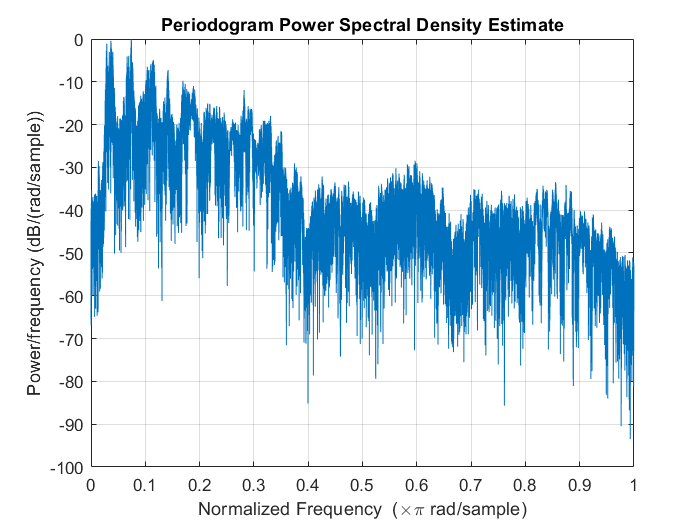

%WRITE YOUR CODE HERE
periodogram(x)

- What information does the periodogram give? 

        ANSWER: identify the dominant periods (or frequencies) of a time series

- Until what frequency does human voice contain significant power density? 

        ANSWER: 155Hz for male and 255 Hz for female

## Thank You!